Clase 5 de Matematicas Aplicadas, 15 de agosto de 2022, en esta clase  resolveremos la siguiente ecuacion diferencial a través de dos formas, la forma antigua y la forma nueva recomendada por Matlab.

Esta es la codificación antigua


$$\frac{d^2y}{dy^2} + 5 \frac{dy}{dt} + 20y = 40$$



$$y(0)=1, \;\;\; y^\prime(0)=0$$


Inicimos introduciendo las variables simbolicas

syms y t 

Introduciomos la ecuación diferencial utilizando operadores 'D'

ec= 'D2y + 5*Dy +20*y=40';
ysol=dsolve(ec,'y(0)=1','Dy(0)=0')

$$ysol = 2-\frac{\sqrt{55}\,{\mathrm{e}}^{-\frac{5\,t}{2}}\,\sin\left(\frac{\sqrt{55}\,t}{2}\right)}{11}-{\mathrm{e}}^{-\frac{5\,t}{2}}\,\cos\left(\frac{\sqrt{55}\,t}{2}\right)$$

Ahora graficamos la solucion

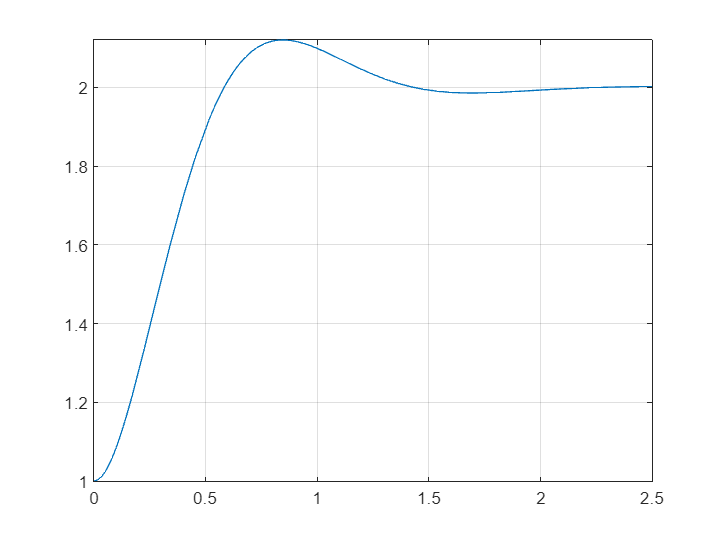

fplot(ysol,[0 2.5]),grid

Ahiora vamos a realizar la solución de la misma ecuación diferencial con el nuevo código recomendado por Matlab

En el nuevo codigo tenemos lo siguiente


$$\frac{d^ny}{dt^n} \to \textrm{diff(y,t,n)}$$


Iniciamos a escribir el codigo,

syms y(t) t;
eqn= diff(y,t,2)+5*diff(y,t,1) + 20*y(t)==40;
Dy=diff(y,t,1);
cond=[y(0)==1, Dy(0)==0]

$$cond = \left(\begin{array}{cc} y\left(0\right)=1 & \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

Generamos la solucíon y graficamos

ySol(t)=dsolve(eqn,cond)

$$ySol(t) = 2-\frac{\sqrt{55}\,{\mathrm{e}}^{-\frac{5\,t}{2}}\,\sin\left(\frac{\sqrt{55}\,t}{2}\right)}{11}-{\mathrm{e}}^{-\frac{5\,t}{2}}\,\cos\left(\frac{\sqrt{55}\,t}{2}\right)$$

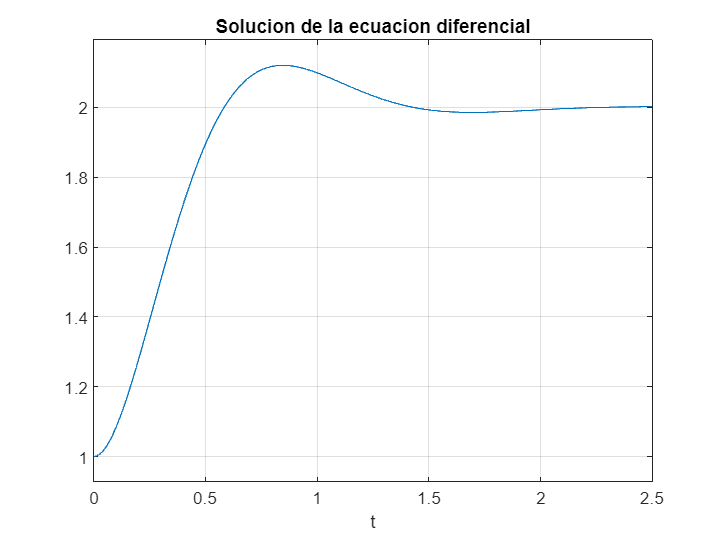

ezplot(ySol,[0 2.5]),grid,title('Solucion de la ecuacion diferencial')